Non-linear

  phi = 0:0.05:1;
  r=10;
% random distributed RDEs/inclusions with random shapes and orientations
  n = 200; % RDEs/inclusions number
  [~,ang]= RandAANG(5,n);
  q = Qvec(ang); 
  a = ones(3,n);
% imposed strain rate
  E  =[0 1 0;1 0 0;0 0 0];
  EI = Inva(E);

% Self-consistent
  eta  = ones(n,1);
  Ne   = 3.*ones(n,1);
  S_SC = zeros(3,3,numel(phi));
  SI_SC= zeros(1,numel(phi));
  vis_SC = zeros(1,numel(phi),1);
  C_SC = zeros(3,3,3,3,numel(phi));
  tic
  for kk = 1:numel(phi)
      if phi(kk)~=0
         ns = int64(n*phi(kk)); 
         eta(1:ns)=r.*ones(ns,1);
      end
      [S_bar,C_bar,~,~,~]= SC_homogenization(E, n, a, q, eta, Ne);
      S_SC(:,:,kk)=S_bar;
      C_SC(:,:,:,:,kk)=C_bar;
      SI_SC(kk)=Inva(S_bar);
      vis_SC(kk)= SI_SC(kk)/EI/2;
  end
  toc

Elapsed time is 53.719301 seconds.


% Mori-Tanaka
  etak = r.*ones(n,1);
  etam = 1;  
  Nk = 3.*ones(n,1);
  Nm = 3;
  S_MT = zeros(3,3,numel(phi));
  SI_MT= zeros(1,numel(phi));
  vis_MT = zeros(1,numel(phi));
  C_MT= zeros(3,3,3,3,numel(phi));
  tic
  for kk = 1:numel(phi)
      [S_bar,C_bar,~,~,~,~,~,~]=MT_homogenization(E,n,a,q,etak,etam,Nk,Nm,phi(kk));
      S_MT(:,:,kk)=S_bar;
      C_MT(:,:,:,:,kk)=C_bar;
      SI_MT(kk)=Inva(S_bar);
      vis_MT(kk)= SI_MT(kk)/EI/2;
  end
  toc

Elapsed time is 61.512196 seconds.


  % 2-phase Mori-Tanaka
  S_MT1=S_MT;
  SI_MT1=SI_MT;
  vis_MT1=vis_MT;
  tic
  for kk=1:numel(phi)
      [S_MT1(:,:,kk),~,~,~,~,~,~,~] = Mori_Tanaka_2phase(E,[1;1;1],10,1,3,3,phi(kk));
      SI_MT1(kk)=Inva(S_MT1(:,:,kk));
      vis_MT1(kk)=SI_MT1(kk)/EI/2;
  end
  toc

Elapsed time is 1.237654 seconds.


 % Eshleby approach 
  S_E = zeros(3,3,numel(phi));
  SI_E= zeros(1,numel(phi));
  vis_E = zeros(1,numel(phi));
  C_E= zeros(3,3,3,3,numel(phi));
  tic
  for kk=1:numel(phi)
      [S_bar,C_bar,e,s,vis]=Eshelby_approach(E,n,a,q,etak,etam,Nk,Nm,phi(kk));
      S_E(:,:,kk)= S_bar;
      C_E(:,:,:,:,kk)=C_bar;
      SI_E(kk)=Inva(S_bar);
      vis_E(kk)=SI_E(kk)/EI/2;
  end
  toc

Elapsed time is 34.791180 seconds.


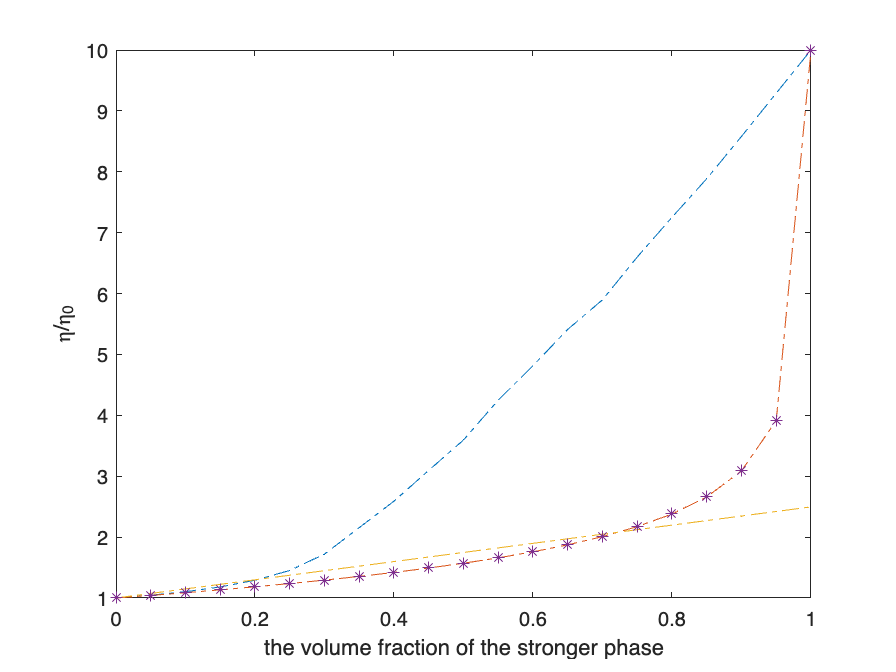

  plot(phi,vis_SC,'-.',phi,vis_MT,'-.',phi,vis_E,'-.',phi,vis_MT1,'*')
  xlim([0 1])
  ylim([1,r])
  xlabel('the volume fraction of the stronger phase')
  ylabel('\eta/\eta_0')